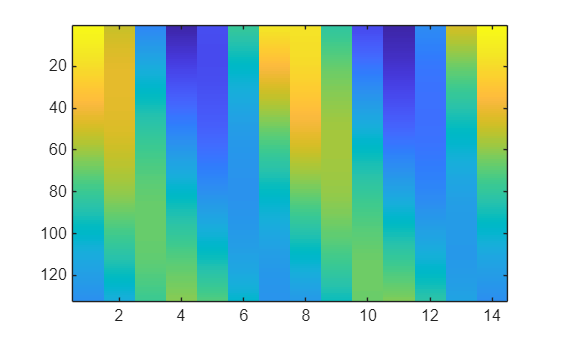

carrier = nrCarrierConfig;
carrier.NSizeGrid = 11;
carrier.SubcarrierSpacing = 30;

channel1 = nrTDLChannel;
channel1.DelayProfile = "NTN-TDL-A";
channel1.MaximumDopplerShift = 7;
channel1.SatelliteDopplerShift = 3.2303e4;

ofdmInfo = nrOFDMInfo(carrier);
channel1.SampleRate = ofdmInfo.SampleRate;

channel1.ChannelResponseOutput = "ofdm-response";
channel1.ChannelFiltering = false;

channel1.NumTimeSamples = sum(ofdmInfo.SymbolLengths(1:carrier.SymbolsPerSlot));
[ofdmResponse,timingOffset] = channel1(carrier);

imagesc(real(ofdmResponse(:,:,1,1)))